a = [1;
2;
3;
4;
5;
6;
];

x = -1:0.01:1;

basis = "StandBasis"

basis = "StandBasis"

poly1 = feval(basis,x,length(a) - 1);
set_coeffs(poly1,a);

fig1


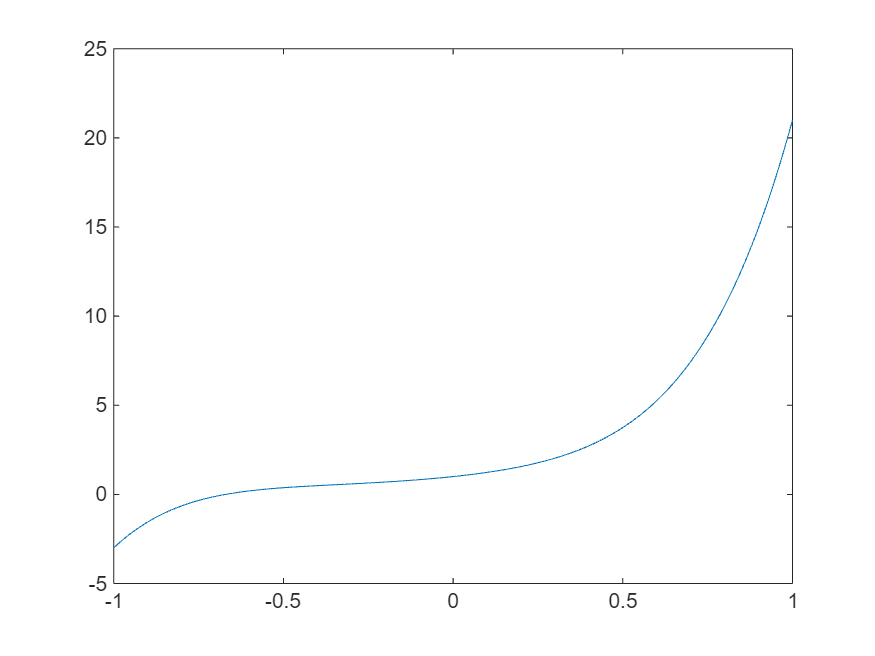

plot(poly1,"basis",false,"value",true);

poly_der = polyder(poly1);
poly_der.coeffs

ans =      2
     6
    12
    20
    30


fig2


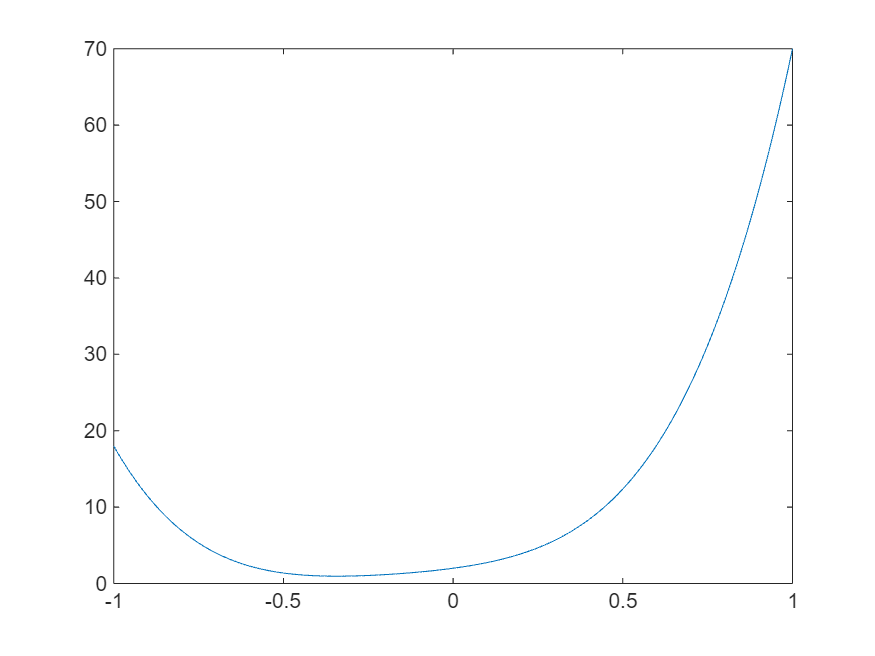

plot(poly_der,"basis",false,"value",true);

fun_par = poly1.as_fun()

fun_par = function_handle with value:
    @(x,P)obj.poly_eval_unnorm(P,x)


fun = @(X)fun_par(X,a)

fun = function_handle with value:
    @(X)fun_par(X,a)


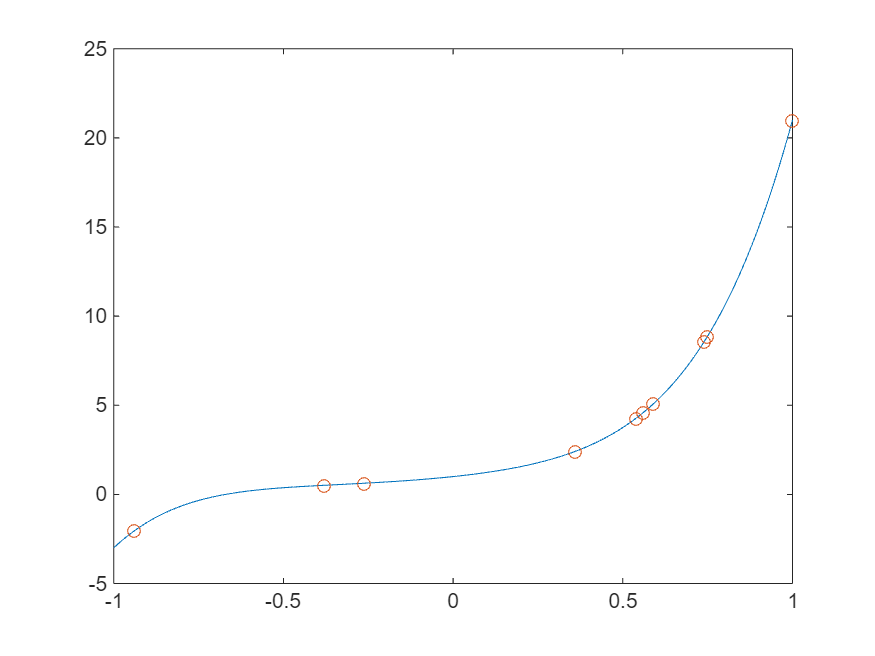

plot(x,poly_eval_unnorm(poly1,a,x));hold on
inds = randi(length(x),[10,1]);
plot(x(inds),fun(x(inds)),"o");hold off

timeit(@()fun(rand(100,1)))

ans = 6.0200e-05

poly1.coeffs

ans =      1
     2
     3
     4
     5
     6


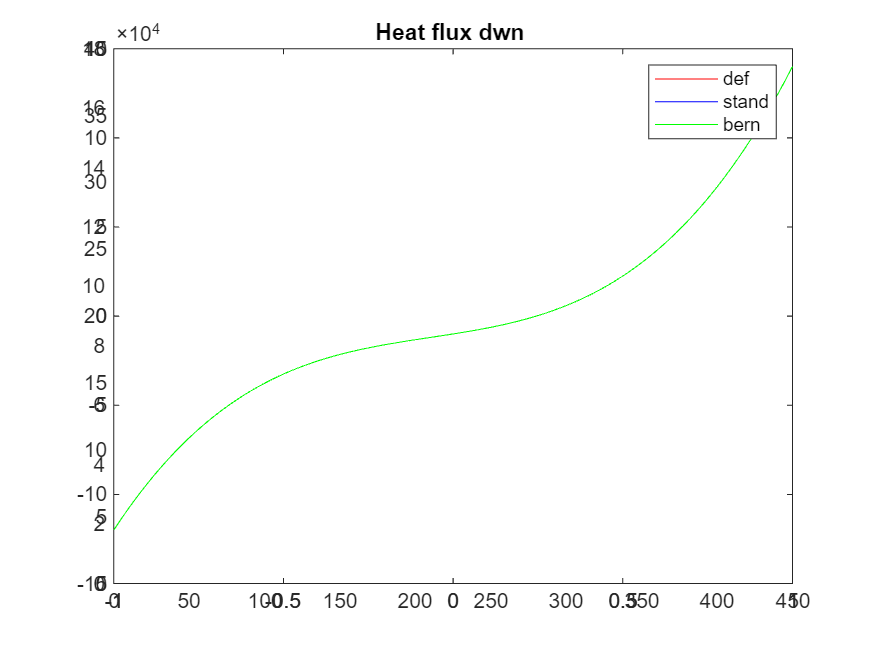

%% testing polynomial evaluation
x = transpose(linspace(-1,1,100));
ppp = [10,2,3,-1]; % standard basis default matlab
y = polyval(ppp,x); % y standard bassis default
poly_stand = StandBasis(x,3);
coeffs_stand = poly_fit(poly_stand,y);
poly_bern = BernsteinBasis(x,3);
coeffs_bern = poly_fit(poly_bern,y);
y_stand_val = poly_eval_unnorm(poly_stand,poly_stand.coeffs,x);
y_bern_val = poly_eval_unnorm(poly_bern,poly_bern.coeffs,x);
plot(x,y,"r",x,y_stand_val,"b", x,y_bern_val,"g"); 
legstr = ["def","stand","bern"]; legend(legstr)

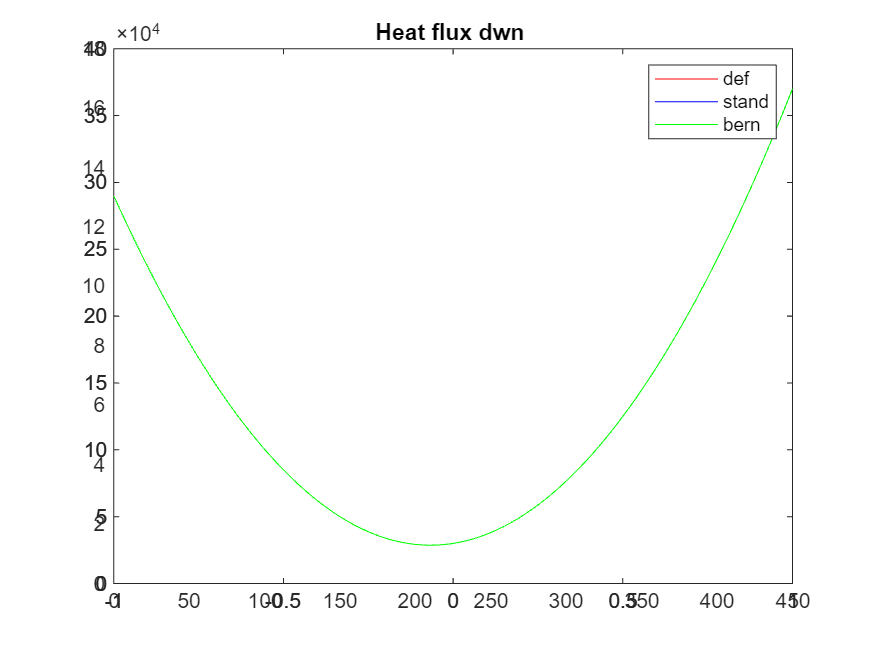


ppp_der = polyder(ppp)'; % def poly derivative coefficients
y_der = polyval(ppp_der,x);% derivative calue
poly_stand_der = poly_der(poly_stand);
poly_bern_der = poly_der(poly_bern);
y_stand_der_val = poly_eval_unnorm(poly_stand_der,poly_stand_der.coeffs,x);
y_bern_der_val = poly_eval_unnorm(poly_bern_der,poly_bern_der.coeffs,x);
plot(x,y_der,"r",x,y_stand_der_val,"b", x,y_bern_der_val,"g"); 
legstr = ["def","stand","bern"]; legend(legstr)

norm(y_bern_der_val - y_der)

ans = 1.0128e-13